# Miami AI demo

## Data Prep

% Define the time range
startTime = datetime('now'); % Current time
endTime = startTime + days(3); % 3 days later
timeVector = startTime:hours(3):endTime; % Sampling every 3 hours

% Convert time to hours elapsed since startTime
timeHours = hours(timeVector - startTime);

% Parameters for the temperature model
avgTemp = 22;       % Average temperature (degrees Celsius)
amp = 5;            % Amplitude of temperature variation
dailyPeriod = 24;   % Period of one full day (in hours)
phaseShift = -pi/2; % Phase shift to set the peak temperature around midday

% Generate temperature data following a logical day/night pattern
temperatureData = avgTemp + amp * sin(2*pi*timeHours/dailyPeriod + phaseShift) + randn(size(timeHours))*0.5;

% Create the table with both variables as column vectors
temperatureForecast = table(timeVector', temperatureData', ...
    'VariableNames', {'Time', 'Temperature'});

% Convert to Timetable
TT = table2timetable(temperatureForecast)

TT = 25x1 timetable
            Time            Temperature
    ____________________    ___________

    18-Mar-2025 16:08:21      16.299   
    18-Mar-2025 19:08:21      17.753   
    18-Mar-2025 22:08:21      22.244   
    19-Mar-2025 01:08:21      25.447   
    19-Mar-2025 04:08:21      26.902   
    19-Mar-2025 07:08:21      26.245   
    19-Mar-2025 10:08:21      22.146   
    19-Mar-2025 13:08:21      18.563   
    19-Mar-2025 16:08:21      17.794   
    19-Mar-2025 19:08:21      18.062   
    19-Mar-2025 22:08:21      22.348   
    20-Mar-2025 01:08:21      25.953   
    20-Mar-2025 04:08:21      26.878   
    20-Mar-2025 07:08:21      25.643   
    20-Mar-2025 10:08:21<

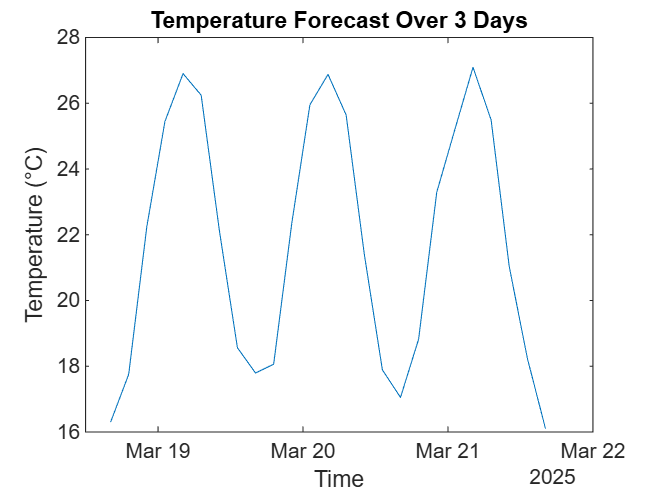

clf
plot(temperatureForecast.Time,temperatureForecast.Temperature)
% Add labels and title to the plot
xlabel('Time');
ylabel('Temperature (°C)');
title('Temperature Forecast Over 3 Days');

## Live tasks

### Retime

% Retime timetable
newTimetable = retime(TT,"regular","linear","TimeStep",hours(1))

newTimetable = 74x1 timetable
            Time            Temperature
    ____________________    ___________

    18-Mar-2025 16:00:00      16.231   
    18-Mar-2025 17:00:00      16.716   
    18-Mar-2025 18:00:00      17.201   
    18-Mar-2025 19:00:00      17.686   
    18-Mar-2025 20:00:00      19.042   
    18-Mar-2025 21:00:00      20.538   
    18-Mar-2025 22:00:00      22.035   
    18-Mar-2025 23:00:00      23.163   
    19-Mar-2025 00:00:00       24.23   
    19-Mar-2025 01:00:00      25.298   
    19-Mar-2025 02:00:00      25.864   
    19-Mar-2025 03:00:00      26.349   
    19-Mar-2025 04:00:00      26.834   
    19-Mar-2025 05:00:00      26.714   
    19-Mar-2025

### Smooth

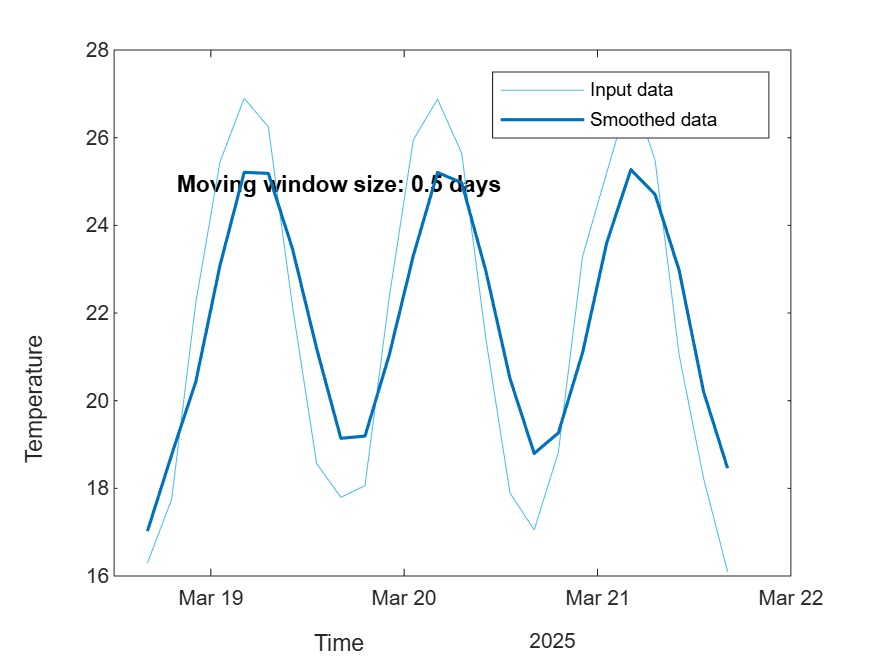

% Smooth input data
[newTable,winSize] = smoothdata(TT,"movmean",days(0.5));

% Display results
figure
plot(TT.Time,TT.Temperature,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(TT.Time,newTable.Temperature,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Temperature")
xlabel("Time")

clear winSize
